การคำนวณหาค่า Q ที่สถานี S1 จากค่า H ระหว่าง Day 61 และ Day 65

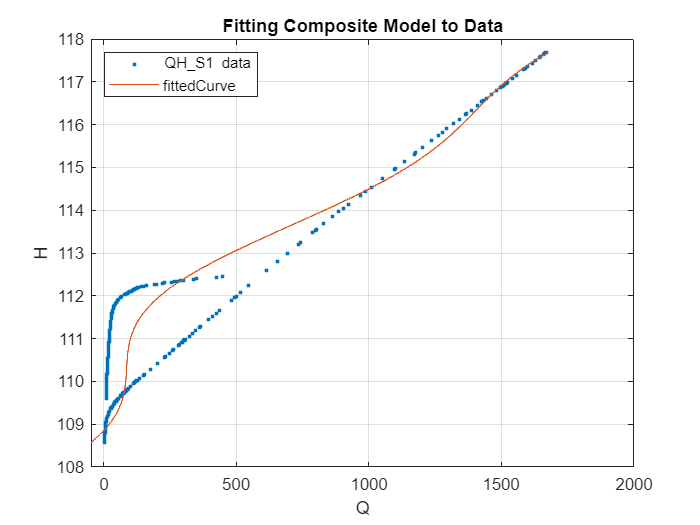

mdl = fittype('a*cos(x+f) + b*x^2 +c*x + d*log(x) + e','coefficients',{'a','b','c','d','e','f'},'independent','x','dependent','y');
fitResult = fit(HS1,QS1,mdl,"StartPoint",[0,0,0,0,0,1]);
coeffs = coeffvalues(fitResult);
a = coeffs(1);
b = coeffs(2);
c = coeffs(3);
d = coeffs(4);
e = coeffs(5);
f = coeffs(6);
nv = a * cos(HS1+f) + b * HS1.^2 + c*HS1 +d * log(HS1) + e;

plot(QS1,HS1,'.')
hold on
plot(nv,HS1)
hold off
grid on
xlabel('Q');
ylabel('H');
title('Fitting Composite Model to Data');
legend({'QH\_S1 data','fittedCurve'},'Location','northwest');

Performance ของการ Fitting

R_squared = 1 - sum((QS1 - nv).^2) / sum((QS1 - mean(QS1)).^2);
MAE = sum(abs(QS1 - nv))/length(QS1);
MSE = (sum((QS1 - nv).^2))/(length(QS1));
fprintf('R_squared = %f\nMAE = %f\nMSE = %f', R_squared,MAE,MSE);

R_squared = 0.967410
MAE = 65.357442
MSE = 9148.282583

Predict และแสดงค่า Q ในวันถัดๆ ไป ของสถานี S1

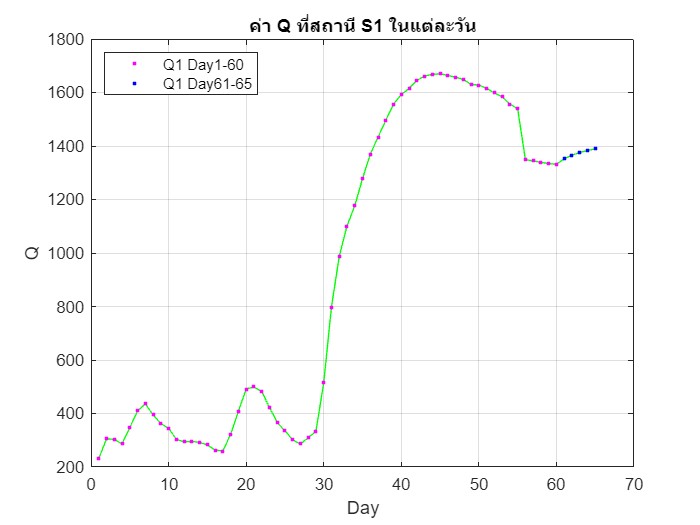

pdQ1 = a*cos(H1(61:65)+f) + b * H1(61:65).^2 + c*H1(61:65) +d * log(H1(61:65)) + e;
Q1 = [Q1(1:60);pdQ1];

plot(1:65,Q1,'g')
hold on
plot(1:60,Q1(1:60),'m.');
plot(61:65,Q1(61:65),'b.');
hold off
grid on
xlabel('Day');
ylabel('Q');
title('ค่า Q ที่สถานี S1 ในแต่ละวัน');
legend({'','Q1 Day1-60','Q1 Day61-65'},'Location','northwest');

fprintf('Day61: %.2f\nDay62: %.2f\nDay63: %.2f\nDay64: %.2f\nDay65: %.2f', Q1(61),Q1(62),Q1(63),Q1(64),Q1(65));

Day61: 1351.95
Day62: 1365.53
Day63: 1375.52
Day64: 1383.16
Day65: 1389.18